# Satellite Image Processing - L*a*b*

*Author: Avalon Royer*

*Student of Geography & Urban Planning at the Université Paris Cité.*

Satellite image processing plays an important role in land use observation and analysis as it allows for the coverage of vast areas, monitoring changes over time, and distinguishing different types of surfaces through multi-spectral data. It is particularly used for visualizing land use in hard-to-reach areas more easily, but also to support decision-making in urban planning, agriculture, and natural resource management, and to detect environmental changes such as deforestation or urbanization more quickly since it provides the ability to compare the same area at different time periods.

## Importing and Reading the Image

To read and display an image in MATLAB, use the `imshow` function after assigning the photo's title to a variable:

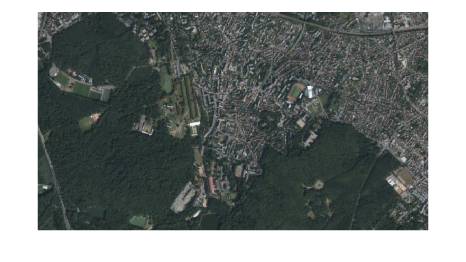

imageName="meudon_satellite.png";
RGB=imread(imageName);
imshow(imageName)

## Conversion from RGB to YCbCr 

The image is converted from the RGB color model to the L*a*b* color model.

I = rgb2lab(RGB);

## Definition of thresholds

The L*a*b* space is composed of three main axes:

- **L** (or Luminance) is the axis representing the brightness of the color, ranging from 0 (black) to 100 (white). It indicates the lightness or darkness of a color without considering its hue or saturation.

- **a** (or Green-Red) is the axis that represents the position of the color between green and red. Negative a values indicate greenish hues while positive a values indicate more reddish hues.

- **b** (or Blue-Yellow) is the axis representing the position of the color between blue and yellow. Negative b values indicate bluish hues while positive b values indicate yellowish hues.

Therefore, the image matrix has 3 main colors for which minimum and maximum thresholds must be chosen to define their intervals and thus highlight the colors that we want to represent in the final production. To do this, simply move each slider to the desired value to choose each min and max threshold for each color.

For example, if we want to represent the portion of the territory covered by green vegetation, we will use the following max and min values:

lMin =10;
lMax =30;
aMin =-10;
aMax =-1;
bMin =-4.5;
bMax =10;

## **Conversion to Black & White Binary Mask**

With the following commands, we will isolate and visualize the parts of the image that fall within specific color ranges by creating a binary image mask based on these thresholds. We will obtain a binary mask (`sliderBW`) in which the pixels within the specified ranges for the three color channels are set to true (1), and all other pixels are set to false (0).

Next, we will simply assign the created mask (`sliderBW`) to BW, and then display the final image using imshow.

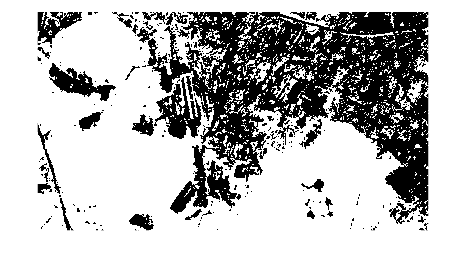

sliderBW = (I(:,:,1) >= lMin ) & (I(:,:,1) <= lMax) & ...
    (I(:,:,2) >= aMin ) & (I(:,:,2) <= aMax) & ...
    (I(:,:,3) >= bMin ) & (I(:,:,3) <= bMax);
BW = sliderBW;
imshow(BW)

## Final Segmentation 

We will isolate the black pixels to remove them from the image, segmenting it to leave only the part selected with the thresholds, in the RGB model.

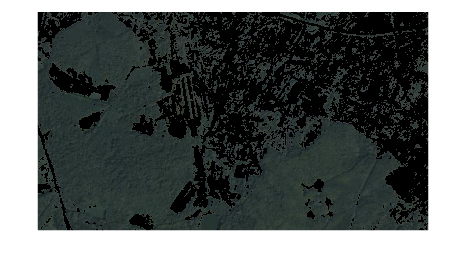

maskedRGBImage = RGB;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
imshow(maskedRGBImage)

## Calculate the Percentage of Vegetation Relative to Urbanized Areas 

Next, we want to calculate the representative percentage of the green vegetation area relative to the entire image selected for analysis. The ratio `sum(sum(BW))/(nbrow*nbcol)` gives the proportion of the image occupied by white pixels, representing the vegetation (prctVege).

[nbrow,nbcol]=size(BW);
prctVege = sum(sum(BW))/(nbrow*nbcol)

prctVege = 0.6094

*Image: Google Maps*